clc;
clear;
close all;

matPath = "2025.08.27.16.12.38_Rec_4.mat";

matPath = "week04_only.mat"

ans = "x_fn"

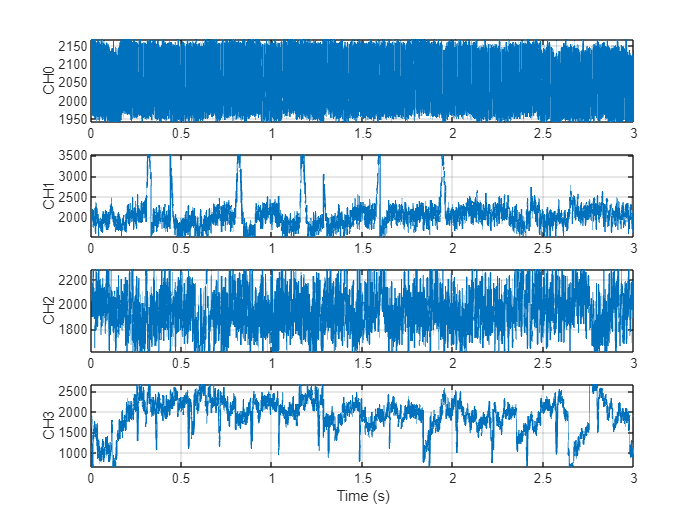

S = load(matPath);
earData = S.earData;

x  = double(earData.channelsData);   % [numCh x N]
fs = earData.sampleRate;


[numCh, N] = size(x);

sec = 3;                             
M = min(N, round(sec*fs));
t = (0:M-1)/fs;

figure('Name','4-Channel Viewer (stacked)','Color','w');

ax = gobjects(numCh,1);

for ch = 1:numCh
    ax(ch) = subplot(numCh,1,ch);

    plot(t, x(ch,1:M), 'LineWidth', 1);
    grid on
    ylabel("CH" + (ch-1))

    y  = x(ch,1:M);
    lo = prctile(y, 1);
    hi = prctile(y, 99);

    if lo == hi
        lo = lo - 1;
        hi = hi + 1;
    end

    ylim([lo hi])
end

xlabel(ax(end), 'Time (s)')

linkaxes(ax, 'x')
sgtitle("First " + sec + " s (channels stacked)")

zoom on
pan on

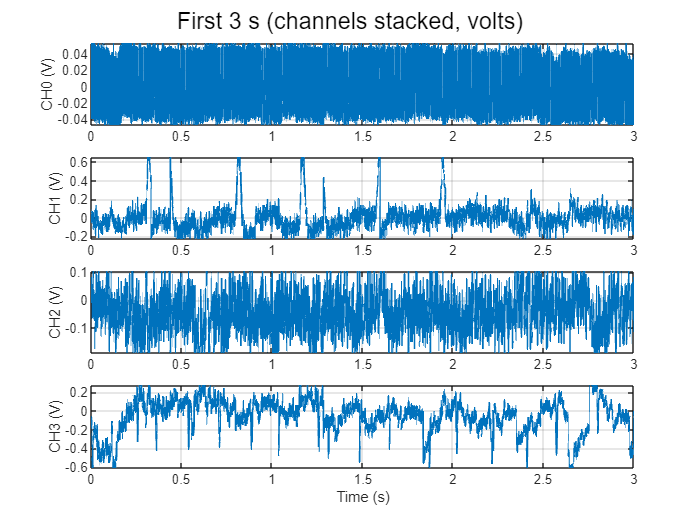

% ===== ADC counts -> Voltage conversion =====
Vref = 1.8;      % volts
Nb   = 12;       % bits

x_V  = (x - 2^(Nb-1)) * (Vref / 2^Nb);   % volts
x_mV = x_V * 1e3;                        % millivolts (optional)

% ===== Plot voltage version (same 4 stacked subplots) =====
figure('Name','4-Channel Viewer (stacked, VOLTS)','Color','w');
ax2 = gobjects(numCh,1);

for ch = 1:numCh
    ax2(ch) = subplot(numCh,1,ch);

    plot(t, x_V(ch,1:M), 'LineWidth', 1);
    grid on
    ylabel("CH" + (ch-1) + " (V)")

    y  = x_V(ch,1:M);
    lo = prctile(y, 1);
    hi = prctile(y, 99);

    if lo == hi
        lo = lo - 1e-3;
        hi = hi + 1e-3;
    end

    ylim([lo hi])
end

xlabel(ax2(end), 'Time (s)')
linkaxes(ax2, 'x')
sgtitle("First " + sec + " s (channels stacked, volts)")

zoom on
pan on

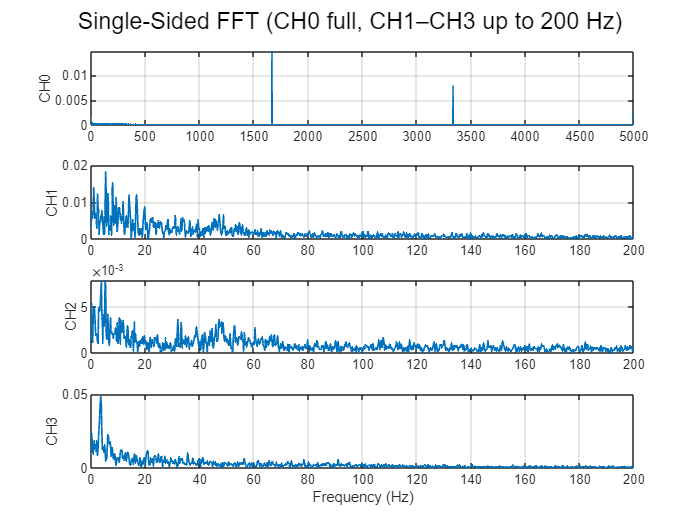

% ===== FFT of all 4 channels (single-sided) =====
secFFT = 5;
L = min(size(x_V,2), round(secFFT*fs));

w = hann(L).';
f = (0:floor(L/2))*(fs/L);

figure('Name','FFT (All Channels)','Color','w');
axF = gobjects(numCh,1);

for ch = 1:numCh
    y = x_V(ch,1:L);
    y = (y - mean(y)) .* w;

    Y  = fft(y);
    P  = abs(Y/L);
    P1 = P(1:floor(L/2)+1);
    if L > 2
        P1(2:end-1) = 2*P1(2:end-1);
    end

    axF(ch) = subplot(numCh,1,ch);
    plot(f, P1, 'LineWidth', 1);
    grid on
    ylabel("CH" + (ch-1))

    if ch ~= 1          % CH1, CH2, CH3
        xlim([0 200])
    end
end

xlabel(axF(end), 'Frequency (Hz)')

sgtitle("Single-Sided FFT (CH0 full, CH1–CH3 up to 200 Hz)")

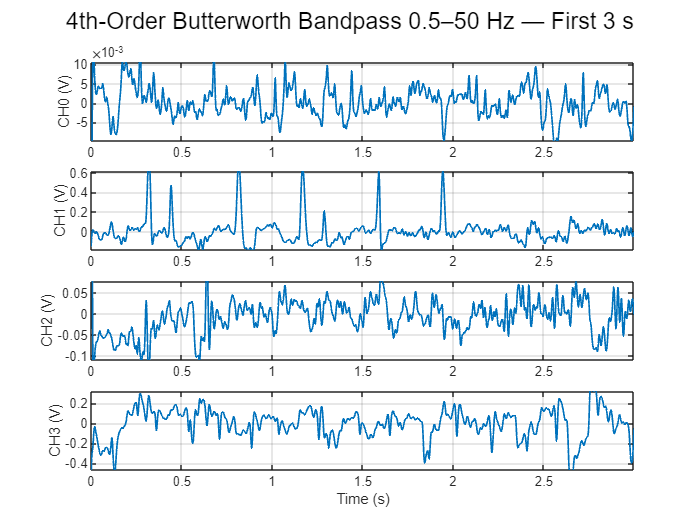

fch = earData.sampleRate;

dBP = designfilt("bandpassiir", ...
    "DesignMethod","butter", ...
    "FilterOrder", 4, ...
    "HalfPowerFrequency1", 0.5, ...
    "HalfPowerFrequency2", 50, ...
    "SampleRate", fch);

x_f = filtfilt(dBP, x_V.').';

sec = 3;
M   = min(N, round(sec*fch));
t   = (0:M-1)/fch;

figure("Name","4th-Order Butter BP 0.5–50 Hz (First 3s)","Color","w");

for ch = 1:numCh
    subplot(numCh,1,ch);
    y = x_f(ch,1:M);

    plot(t, y, "LineWidth", 1); grid on
    ylabel("CH" + (ch-1) + " (V)")

    lo = prctile(y,1); hi = prctile(y,99);
    if lo == hi, lo = lo - 1e-3; hi = hi + 1e-3; end
    ylim([lo hi])

    xlim([t(1) t(end)])
end

xlabel("Time (s)")
sgtitle("4th-Order Butterworth Bandpass 0.5–50 Hz — First " + sec + " s")

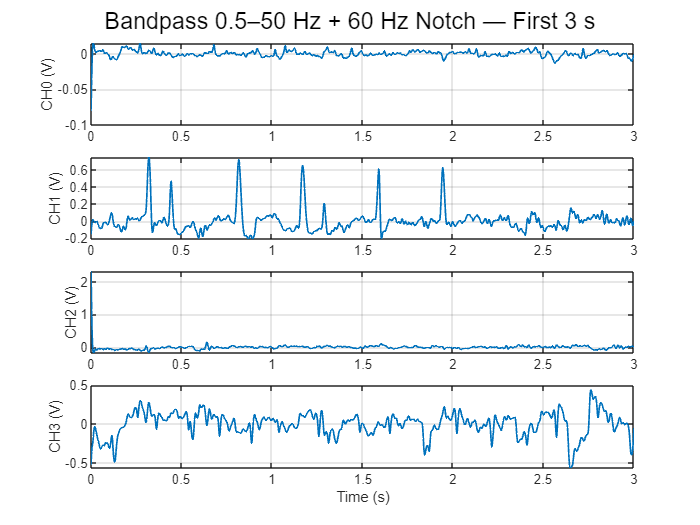

wo = 60/(fch/2);
bw = wo/35;
[bN,aN] = iirnotch(wo, bw);

x_fn = filtfilt(bN, aN, x_f.').';

sec = 3;
M = min(N, round(sec*fch));
t = (0:M-1)/fch;

figure("Name","After 60 Hz Notch (First 3s)","Color","w");

for ch = 1:numCh
    subplot(numCh,1,ch);
    y = x_fn(ch,1:M);
    plot(t, y, "LineWidth", 1); grid on
    ylabel("CH" + (ch-1) + " (V)")
end

xlabel("Time (s)")
sgtitle("Bandpass 0.5–50 Hz + 60 Hz Notch — First 3 s")

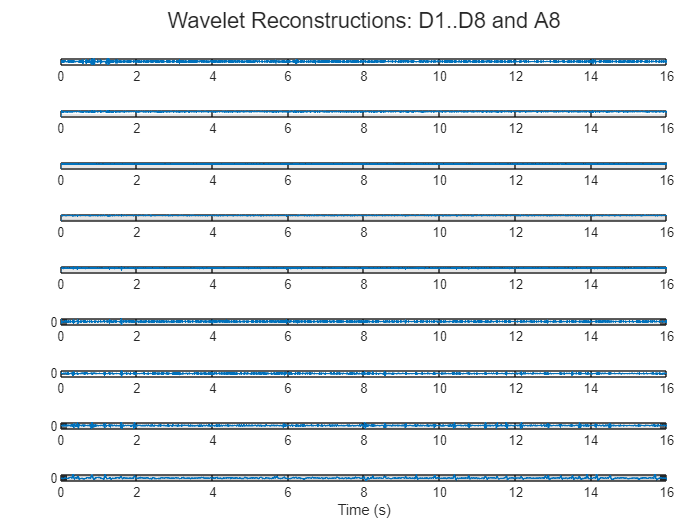

ch  = 2;
sig = double(x_fn(ch,:));
sig = sig(:).';                        % row vector forcing
fs  = earData.sampleRate;              % sampling frequency

sec = 16;
M   = min(numel(sig), round(sec*fs));
sig = sig(1:M);                        % considering only the first 3 secs of the signal

winSec = 0.8;
W = max(3, 2*floor((winSec*fs)/2)+1);
base = movmedian(sig, W, "Endpoints","shrink");
sig0  = sig - base;                    % signal dragged to a common baseline

wname = "bior3.5";                     % for smooth transient (linear-phase-ish)
fCut  = 6;
l     = 8;

[C0,L0] = wavedec(sig0, l, wname);



A = cell(l,1);      % A{s} = approximation coeffs at level s
D = cell(l,1);      % D{s} = detail coeffs at level s
xA_s = cell(l,1);   % reconstructed approximation signal at level s (optional)
xD_s = cell(l,1);   % reconstructed detail signal at level s (optional)

for s = 1:l
    A{s}   = appcoef(C0, L0, wname, s);
    D{s}   = detcoef(C0, L0, s);
    xA_s{s}= wrcoef("a", C0, L0, wname, s);
    xD_s{s}= wrcoef("d", C0, L0, wname, s);
end

levelsToShow = [1 2 3 l];
% ---- Plot all details D1..Dl and final approximation Al ----
t = (0:numel(sig0)-1)/fs;

figure("Color","w","Name","All D-levels + Final A");
tl = tiledlayout(l+1, 1, "TileSpacing","compact", "Padding","compact");

for s = 1:l
    nexttile
    plot(t, xD_s{s}, "LineWidth", 1); grid on
    ylabel("D" + s)
end

nexttile
plot(t, xA_s{l}, "LineWidth", 1); grid on
ylabel("A" + l)
xlabel("Time (s)")

title(tl, "Wavelet Reconstructions: D1..D" + l + " and A" + l)

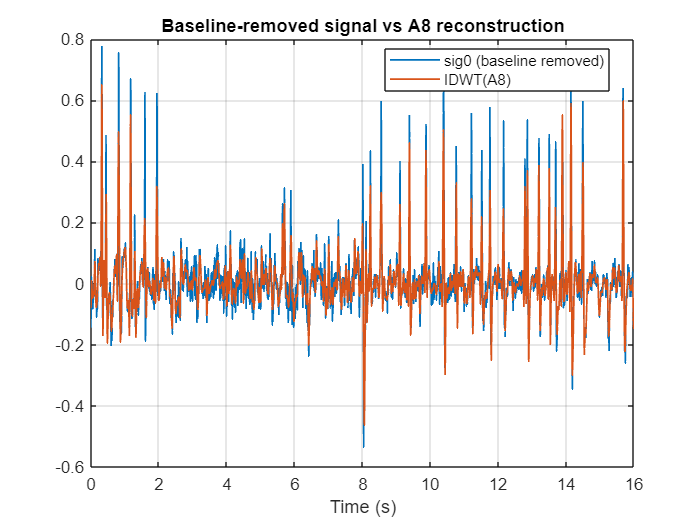

A_l = A{l};         % raw approximation coeffs at your final level
D_l = D{l};         % raw detail coeffs at your final level
xA  = xA_s{l};      % matches your current xA line


% ---- Inverse-DWT reconstruction of A8 (explicit) + plot ----
A8 = appcoef(C0, L0, wname, 8);      % approximation coefficients at level 8
xA8_idwt = wrcoef("a", C0, L0, wname, 8);  % reconstructed time-domain signal from A8
xA8_idwt = xA8_idwt(1:numel(sig0));

t = (0:numel(sig0)-1)/fs;


figure("Color","w","Name","sig0 vs IDWT(A8)");
plot(t, sig0, "LineWidth", 1); hold on; grid on
plot(t, xA8_idwt, "LineWidth", 1);
legend("sig0 (baseline removed)", "IDWT(A8)", "Location","best")
xlabel("Time (s)")
title("Baseline-removed signal vs A8 reconstruction")

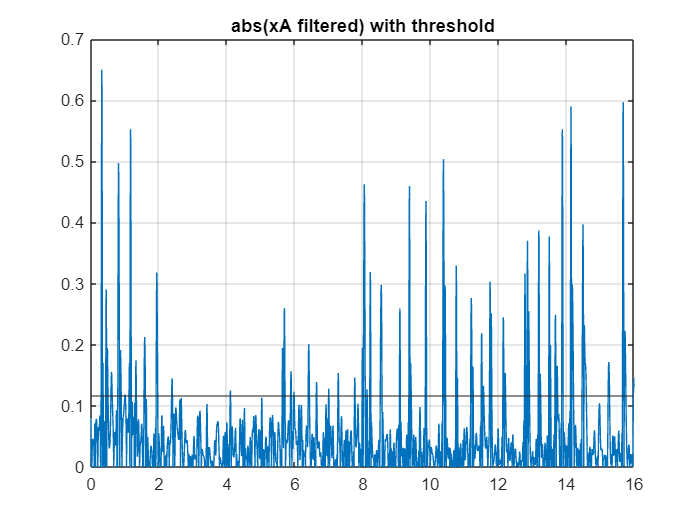


xA      = wrcoef("a", C0, L0, wname, l);
xA      = xA(1:numel(sig0));


blinkHeight = 0.75;
blinkWidth  = 0.0433;

opts.sgolayOrder = 3;
opts.sgolayFrame = 2*floor((0.01*fs)/2)+1;   % ~10 ms

opts.minHeight  = max(1.5*mad(xA,1), 0.18*max(abs(xA)));
opts.wRangeSec = [0.02 0.14];
opts.minDistSec = 0.18;

opts.edgeFrac    = 0.05;
xf = sgolayfilt(xA, opts.sgolayOrder, opts.sgolayFrame);
t  = (0:numel(xf)-1)/fs;

figure; plot(t, abs(xf)); grid on; hold on
yline(opts.minHeight);
title("abs(xA filtered) with threshold");

[rRef, blink] = make_asym_gauss_reference(xA, fs, opts);
fprintf("peaks=%d | max|xA|=%.3f | max|rRef|=%.3f\n", ...
    numel(blink.locs), max(abs(xA)), max(abs(rRef)));

peaks=35 | max|xA|=0.650 | max|rRef|=1.000


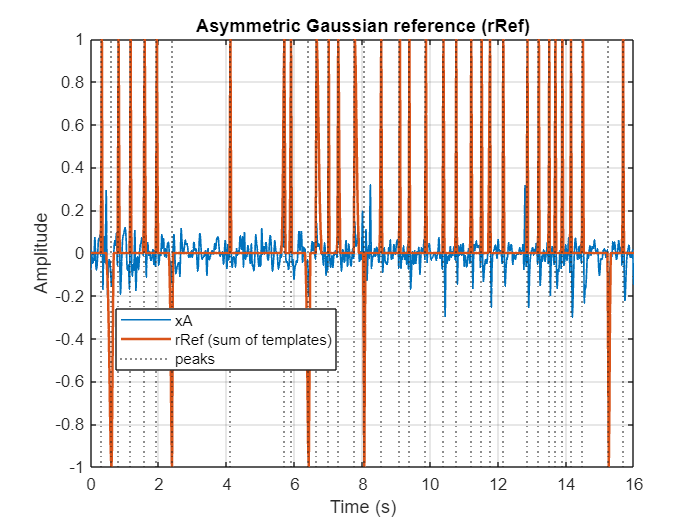

% --- after you run: [rRef, blink] = make_asym_gauss_reference(xA, fs, opts);

t = (0:numel(xA)-1)/fs;

% 1) Full overlay (context)
figure("Color","w","Name","xA vs rRef");
plot(t, xA, "LineWidth", 1); grid on; hold on
plot(t, rRef, "LineWidth", 1.5)
xline(t(blink.locs), ":");
legend("xA","rRef (sum of templates)","peaks","Location","best")
xlabel("Time (s)"); ylabel("Amplitude"); title("Asymmetric Gaussian reference (rRef)")

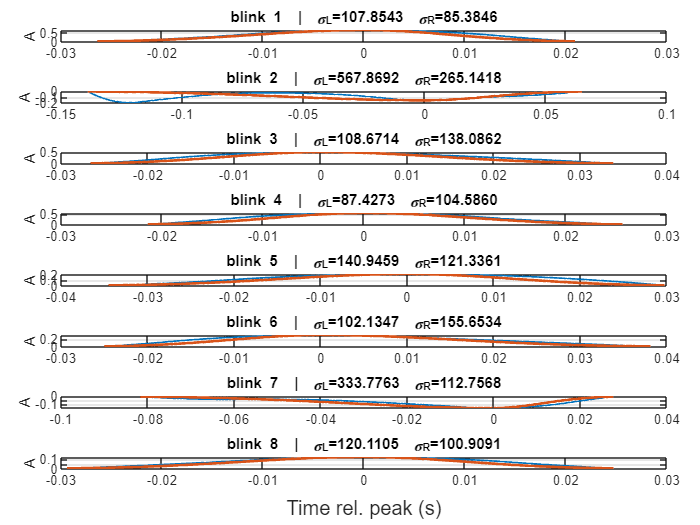

K = min(numel(blink.locs), 8);   % show first few
figure("Color","w","Name","Templates");
tl = tiledlayout(K,1,"TileSpacing","compact","Padding","compact");

for i = 1:K
    L  = blink.left(i);  R  = blink.right(i);  t0 = blink.locs(i);
    n  = L:R;
    tt = (n - t0)/fs;

    s1 = blink.sigma1(i); 
    s2 = blink.sigma2(i);

    g = zeros(size(n));
    m = n <= t0;
    g(m)  = exp(-((n(m)-t0).^2) ./ (2*s1^2));
    g(~m) = exp(-((n(~m)-t0).^2) ./ (2*s2^2));
    g = sign(blink.pks(i)) * g;
    g = g / max(abs(g));                 % unit template
    gs = abs(xA(t0)) * g;                % scaled for overlay

    nexttile
    plot(tt, xA(n), "LineWidth", 1); grid on; hold on
    plot(tt, gs, "LineWidth", 1.6)
    xline(0,":")
    ylabel("A")
    title("blink "+i+"  |  \sigma_L="+num2str(s1,"%.4f")+"  \sigma_R="+num2str(s2,"%.4f"))
end
xlabel(tl,"Time rel. peak (s)")

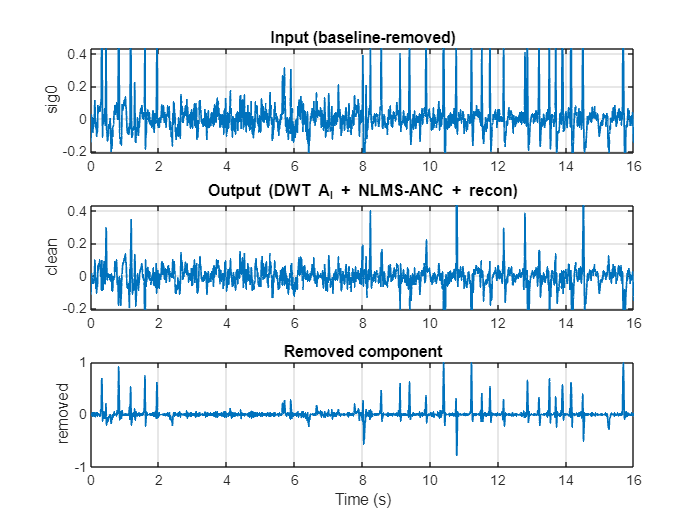

mask = zeros(size(rRef));
for i = 1:numel(blink.locs)
    L = max(1, blink.left(i));
    R = min(numel(rRef), blink.right(i));
    mask(L:R) = 1;
end
rRef = rRef .* mask;

r = rRef;
if rms(r) > 0
    r = r * (rms(xA)/(rms(r)+eps));
end

Mtap = min(256, max(32, round(0.02*fs)));
mu   = 0.1;
eps0 = 1e-6;

xA_clean = nlms_anc(xA, r, Mtap, mu, eps0);

[Cx,Lx] = wavedec(xA_clean, l, wname);
Cclean  = C0;
a1 = 1;        a2 = L0(1);
d1 = a2+1;     d2 = a2 + L0(2);

Cclean = C0;
Cclean(a1:a2) = Cx(a1:a2);
Cclean(d1:d2) = Cx(d1:d2);

sigClean = waverec(Cclean, L0, wname);
sigClean = sigClean(1:numel(sig0));

t  = (0:numel(sig0)-1)/fs;
lo = prctile([sig0(:); sigClean(:)], 1);
hi = prctile([sig0(:); sigClean(:)], 99);

figure("Color","w","Name","Blink removal pipeline");
subplot(3,1,1); plot(t,sig0,"LineWidth",1); grid on; ylim([lo hi]); ylabel("sig0");     title("Input (baseline-removed)");
subplot(3,1,2); plot(t,sigClean,"LineWidth",1); grid on; ylim([lo hi]); ylabel("clean"); title("Output (DWT A_l + NLMS-ANC + recon)");
subplot(3,1,3); plot(t,sig0-sigClean,"LineWidth",1); grid on; ylabel("removed"); xlabel("Time (s)"); title("Removed component");

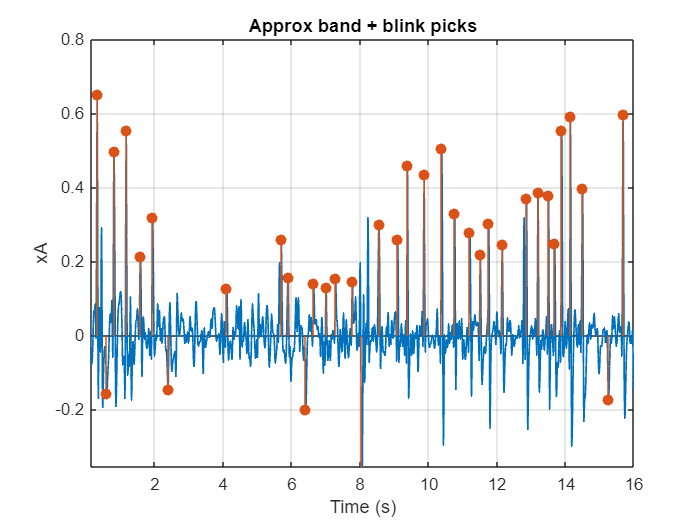

figure("Color","w","Name","Detected blink locations");
plot(t,xA,"LineWidth",1); grid on; hold on
stem(blink.locs/fs, xA(blink.locs), "filled");
xlabel("Time (s)"); ylabel("xA"); title("Approx band + blink picks");

fprintf("||removed|| = %.4f\n", norm(sig0 - sigClean));

||removed|| = 46.6040


save("week04_only.mat","x_fn","earData","-v7.3")


function e = nlms_anc(x, r, Mtap, mu, eps0)
x = x(:).'; r = r(:).';
N = numel(x);
w = zeros(Mtap,1);
e = zeros(1,N);
rPad = [zeros(1,Mtap-1) r];
for n = 1:N
    rv = rPad(n+Mtap-1:-1:n).';
    y  = w.'*rv;
    e(n) = x(n) - y;
    w  = w + (mu/(eps0 + rv.'*rv))*e(n)*rv;
end
end

function [rRef, blink] = make_asym_gauss_reference(xA, fs, opts)
xA = xA(:).';
N  = numel(xA);

if ~isfield(opts,'sgolayOrder'),   opts.sgolayOrder = 3; end
if ~isfield(opts,'sgolayFrame'),   opts.sgolayFrame = max(11, 2*floor(0.05*fs/2)+1); end
if ~isfield(opts,'minHeight'),     opts.minHeight   = 0.1*max(abs(xA)); end
if ~isfield(opts,'wRangeSec'),     opts.wRangeSec   = [0.10 0.50]; end
if ~isfield(opts,'minDistSec'),    opts.minDistSec  = 0.25; end
if ~isfield(opts,'edgeFrac'),      opts.edgeFrac    = 0.05; end

frame = opts.sgolayFrame; 
frame = min(frame, N - mod(N+1,2));
frame = frame + (mod(frame,2)==0);

xf = sgolayfilt(xA, opts.sgolayOrder, frame);

wMin = max(1, round(opts.wRangeSec(1)*fs));
wMax = max(wMin, round(opts.wRangeSec(2)*fs));
dMin = max(1, round(opts.minDistSec*fs));

[pksAbs, locs, wAbs] = findpeaks(abs(xf), ...
    'MinPeakHeight', opts.minHeight, ...
    'MinPeakDistance', dMin, ...
    'MinPeakWidth', wMin, ...
    'MaxPeakWidth', wMax);

pks = xf(locs);

rRef = zeros(1,N);

blink.locs   = locs;
blink.pks    = pks;
blink.wAbs   = wAbs;
blink.sigma1 = zeros(size(locs));
blink.sigma2 = zeros(size(locs));
blink.left   = zeros(size(locs));
blink.right  = zeros(size(locs));

kEdge = sqrt(2*log(1/opts.edgeFrac));

for i = 1:numel(locs)
    t0 = locs(i);
    A  = pks(i);
    Ap = abs(A);
    thr = opts.edgeFrac * Ap;

    L = t0;
    while L > 1 && abs(xf(L)) > thr
        L = L - 1;
    end

    R = t0;
    while R < N && abs(xf(R)) > thr
        R = R + 1;
    end

    d1 = max(1, t0 - L);
    d2 = max(1, R - t0);

    s1 = d1 / kEdge;
    s2 = d2 / kEdge;

    n = L:R;
    g = zeros(size(n));

    idxL = n <= t0;
    idxR = n >  t0;

    g(idxL) = exp(-((n(idxL)-t0).^2) ./ (2*s1^2));
    g(idxR) = exp(-((n(idxR)-t0).^2) ./ (2*s2^2));

    g = sign(A) * g;
    g = g / max(abs(g));

    rRef(n) = rRef(n) + g;

    blink.sigma1(i) = s1;
    blink.sigma2(i) = s2;
    blink.left(i)   = L;
    blink.right(i)  = R;
end
end